**Lab 2: Probability, Distributions, and Statistical Questions**

**Problem 1**

I will assume that in 1 day, the average cosmic-ray background is 3, and the number of gamma-rays emitted by my sample is 7.1. 

*A) Show how the probability distribution changes as you integrate for more days.*

First, I want to setup the probability distribution for 1 day.

lambda = 3;
pDist1day = makedist("Poisson","lambda",lambda);

Next, I want to account for multiple days, so I will multiply the range and the lambda of the distribution by N, where N is the number of days.

N = 5; %choice to be specified later on
lambdaN = lambda*N;
x = 0:20;%vector of x inputs
x1 = 0:(20*N);
pdfPDist1day = pdf(pDist1day,x);
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 15


pdfPDistNdays = pdf(pDistNdays,x1);

pdfPDistNdays is now the probability density function for N days.

We can now compare the pdfs for 1 day and N days, varying N, and see how they change.

subplot(3,1,1);
plot(x,pdfPDist1day);
title('pdf for 1 day');
subplot(3,1,2);
plot(x1,pdfPDistNdays);
name = strcat('pdf for ',num2str(N),' days');
title(name);

Change N to be 12 days.

N = 12;
lambdaN = lambda*N;
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 36


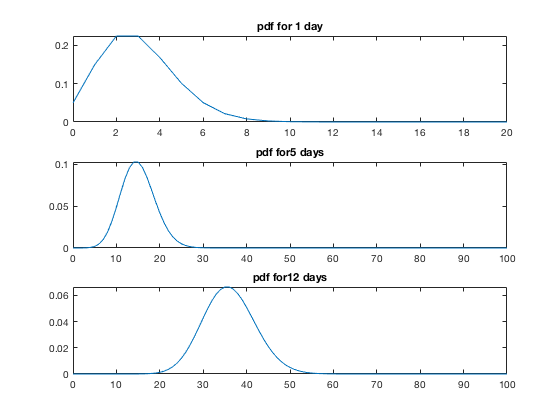

pdfPDistNdays = pdf(pDistNdays,x1);
subplot(3,1,3);
plot(x1,pdfPDistNdays);
name = strcat('pdf for ',num2str(N),' days');
title(name);

Let's look at them in a log y-scale as well.

figure;
subplot(3,1,1);
plot(x,pdfPDist1day);
set(gca,'YScale','log');
title('pdf for 1 day log plot');
subplot(3,1,2);
N = 5;
lambdaN = lambda*N;
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 15


pdfPDistNdays = pdf(pDistNdays,x1);
plot(x1,pdfPDistNdays);
set(gca,'YScale','log');
name = strcat('pdf for ',num2str(N),' days log plot');
title(name);
subplot(3,1,3);
N = 12;
lambdaN = lambda*N;
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 36


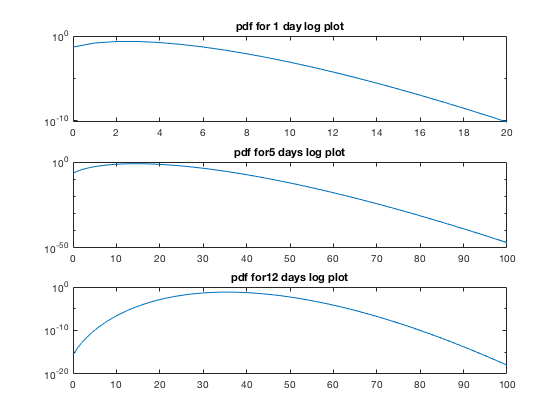

pdfPDistNdays = pdf(pDistNdays,x1);
plot(x1,pdfPDistNdays);
set(gca,'YScale','log');
name = strcat('pdf for ',num2str(N),' days log plot');
title(name);

Although the changes on the log scale may not be very noticeable, they would be if we drastically increased the number of days.

We can see that changing the number of days spreads the distribution out. The total integral of the distribution is still limited to 1, as it is a probability distribution, but now integrating up to a certain value on both distributions will give different results as they will encapsulate different areas.

*B) Show that after 5 days, the summed probability distribution is still a Poisson distribution. Explain why this makes sense from a mathematical and conceptual point of view.*

First, reproduce the pdf with N = 5 days.

N = 5;%setting the number of days
lambdaN = lambda*N;
pDistNdays = makedist("Poisson","lambda",lambdaN)

pDistNdays =   PoissonDistribution

  Poisson distribution
    lambda = 15


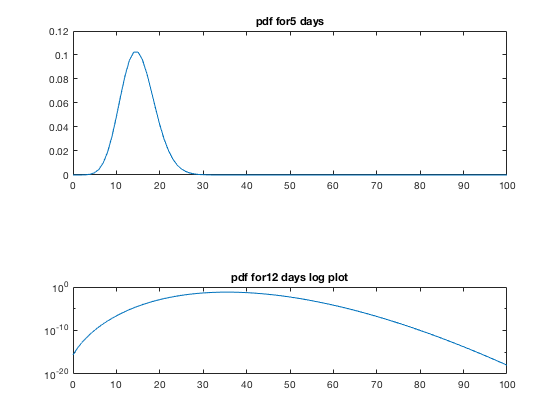

pdfPDistNdays = pdf(pDistNdays,x1);
subplot(2,1,1);
plot(x1,pdfPDistNdays);
name = strcat('pdf for ',num2str(N),' days');
title(name);

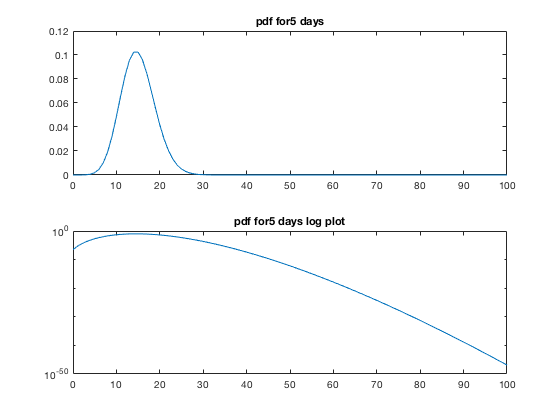

subplot(2,1,2);
plot(x1,pdfPDistNdays);
set(gca,'YScale','log');
name = strcat(name,' log plot');
title(name);

In order to check that these are indeed still Poisson distributions, we can check by doing a convolution of the original Poisson distribution for 1 day with itself N times.

pdfCheck = conv(pdfPDist1day,pdfPDist1day);
for i = 1:(N-2)
    pdfCheck = conv(pdfCheck,pdfPDist1day);
end
x = 0:100;

Compare plots side by side.

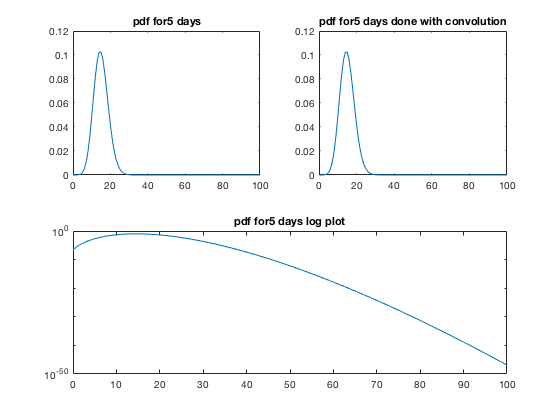

subplot(2,2,1);
plot(x1,pdfPDistNdays);
name = strcat('pdf for ',num2str(N),' days');
title(name);
subplot(2,2,2);
plot(x,pdfCheck);
name1 = strcat(name,' done with convolution');
title(name1);

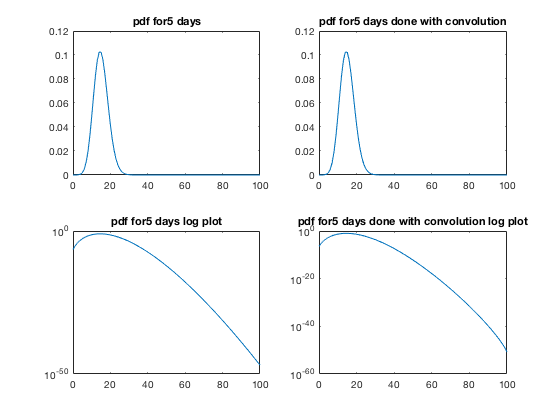

subplot(2,2,3);
plot(x1,pdfPDistNdays);
set(gca,'YScale','log');
title(strcat(name,' log plot'));
subplot(2,2,4);
plot(x,pdfCheck);
set(gca,'YScale','log');
title(strcat(name1,' log plot'));

These look identically the same. This makes sense because when we're changing the range and the "mean" of the distribution by multiplication, we are essentially saying "what if I were to repeat this measurement N number of times." The convolution calculates the sum of the probabilities over all possible offsets, and since I've convolved it N times, the two are identical.

*C) Show how the probability distribution evolves as you average days. Calculate for many different ranges of days, and explore the shape of the distribution as the number of days becomes larger. Discuss this in relation to both B) and the central limit theorem.*

Divide the range of x after the convolution by the number of convolutions (days), so now instead of the range of x being 0:20, it will be 0:10 with the same number of steps.

As we increase the number of days over which the distribution is averaged, it starts approaching a Gaussian distribution. This is exactly what is stated by the central limit theorem, and we can also see from part B that increasing the number of days (although it was not done here to a large number of days) appears to shift the Poisson distribution to be more like a Gaussian.